# Neurotech 2021 - Notebook 2 - Part 1

## Conditional probability, Bayes Theorem

**Sam Michalka - Olin College of Engineering**

## Commentary on this assignment

This assignment builds upon the content in the MIT OpenCourseware course: Introduction to Probability and Statistics. If their style does not work well for you, there are various other resources available. Feel free to reach out to Sam or the course assistants if you're having trouble finding resources.

## Skills and topics

- Conditional probabilities 

- Bayes Theorem / Bayes Rule

- Calculating probabilities from data

## Preliminary reading on Bayes Theorem

I strongly suggest that you read these 12 pages: [https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading3.pdf](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading3.pdf)  However, depending on your preferred approach and experience with Bayes, you may want to first start working on the exercises below and then refer to this document or you might choose to read it first and then proceed. 

This document begins by reviewing conditional probability, then it introduces two important rules that are fundamental to Bayes Theorem (also called Bayes Rule, Bayes Law, and that thing Bayes gets credit for but was originally shown by LaPlace). The first of these rules is the multiplication rule and the second is the law of total probabiltiy. Then the reading explains how to use probability trees to organize information about conditional probabilities, which can become really helpful since it's easy to get confused with a bunch of similar sounding terms. The reading then defines independence, and then introduces Bayes Theorem. I've included a few key notes below for your reference. If you want extra practice with Bayes Theorem after you have finished this assignment, Netflix recommends you try these: [https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/reading-questions-3/](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/reading-questions-3/) 

### Multiplication Rule


$$P\left(A\cap B\right)=P\left(A\left|B\right.\right)\cdot P\left(B\right)$$


### Law of Total Probability

Suppose the sample space Ω is divided into 3 disjoint events $B_1 ,B_2 ,\textrm{and}\;B_3$ (see figure). 

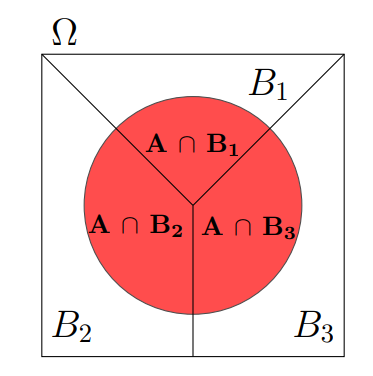

Then for any event A: 


$$P\left(A\right)=P\left(A\left|B_1 \right.\right)\cdot P\left(B_1 \right)+P\left(A\left|B_2 \right.\right)\cdot P\left(B_2 \right)+P\left(A\left|B_3 \right.\right)\cdot P\left(B_3 \right)$$


This just says that the probability of A is just the sum of the probabilities of all those red slices of pie in the figure.

### Independence

Two events A and B are independent if $P\left(A\cap B\right)=P\left(A\right)\cdot P\left(B\right)$.

This is sometimes easier to think about in terms of conditional probabilities:

1) $\textrm{If}\;P\left(B\right)\not= 0,\textrm{then}\;$A and B are independent if, and only if, P(A|B) = P(A).

2) $\textrm{If}\;P\left(A\right)\not= 0,\textrm{then}\;A\;\textrm{and}\;B\;\textrm{are}\;\textrm{independent}\;\textrm{if},\textrm{and}\;\textrm{only}\;\textrm{if},P\left(B\left|A\right.\right)=P\left(B\right)\ldotp$

In other words, knowing that B occurred does not change the probability that A occurred (and vice versa). 

### Bayes' Theorem

The equation for Bayes Theorem is:

$P\left(B\left|A\right.\right)=\frac{P\left(A\left|B\right.\right)\cdot P\left(B\right)}{P\left(A\right)}$ or $\textrm{posterior}=\frac{\textrm{likelihood}\cdot \textrm{prior}}{\textrm{marginal}\;\textrm{likelihood}}$

Often, P(A) is calculated using the law of total probability. In some cases, we don't actually need to calculate P(A) to get the information we need, and we can write this as the posterior is proportional to the likelihood times the prior: $P\left(B\left|A\right.\right)\propto P\left(A\left|B\right.\right)\cdot P\left(B\right)$

## Bayes Theorem with Trees and "Hand Calculations"

For this section, I suggest that you start by working on paper. I also suggest that you use the tree strategy to map out the problem. Feel free to use Matlab or a calculator to do the actual calculations.

I have two boxes of cupcakes.... yes I'm that lucky. Box 1 has 4 chocolate cupcakes and 8 vanilla cupcakes. Box 2 has 8 chocolate cupcakes and 2 vanilla cupcakes. My charming child has appeared on the scene and stolen a cupcake. 

#### Exercise 1: What is the probability of selecting a vanila cupcake? 

p_v = 10/22

p_v = 0.4545

Box 2 is slightly easier to reach, so I estimate the probability that my kid took a cupcake from Box 2 as 0.6. 

#### Exercise 2: What is the probability of selecting a vanila cupcake with this new information about box location? 

%probability vanilla from box 1
p_v1 = .4 * 2/3;
%probability vanilla from box 2
p_v2 = .6 * .2;
%probability vanilla overall
p_v = p_v1 + p_v2

p_v = 0.3867

Then, I see that my kid's face is covered with chocolate frosting.

#### Exercise 3: What is the probability that my kid stole a cupcake from Box 2 given the evidence on their face?

%probability Box 2 given chocolate is known
%TODO: Check
p_b2 = 2/3

p_b2 = 0.6667

## Bayes Theorem and the Base Rate Fallacy

In this section, we'll explore the base rate fallacy using the data from last week's Parkinson's disease screening example. The data are [here](https://drive.google.com/file/d/1YsgbEEB8HhqZwhuBItDqC4-GZturOI6N/view), or probably already downloaded on your computer.

load('Parkinsons2021.mat'); %You will need to replace this text with your own file location.
% The ../ means to go up one directory from the directory you are currently in

#### Exercise 4: If you randomly select someone from your study group who tested positive according to your screening test (diagnosis ==1), what is the probability that they actually have Parkinson’s disease?

%probability reality == 1 given diagnosis == 1
sum(data.reality == 1 & data.diagnosis == 1) / sum(data.diagnosis == 1)

ans = 0.8873

#### Exercise 5: Now, let’s imagine this becomes a regular screening for adults 45 and over. [This paper](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6039505/) estimates “the overall prevalence of PD among those aged ≥45 years to be 572 per 100,000.”  What is the probability that a random person who gets a positive test result (screen=1) actually has Parkinson’s disease? What are your thoughts on this number?

%use bayes theorem: P(D+|T+) = (P(T+|D+)*P(D+))/P(T+)
%TODO: how did i mess this up?
%Orignal-- WRONG
% p_dpos = .0057; %based on table diagnosis == 1/ height(table)
% p_dpos = sum(data.diagnosis == 1) / height(data)
% false_pos = .9943*.1217
% true_pos = .0057*.9582

p_dpos = 0.5399

false_pos = 0.1210

true_pos = 0.0055

p_tpos = 0.1265

p_tpos_g_dpos = 0.0055

p_dpos_g_tpos = 0.0233

% p_tpos = false_pos + true_pos %calculated by looking at tree (D-*T+ + D+*T+)
% p_tpos_g_dpos = .9582 * .0057 %calculated by looking at tree (D+*T+)
% p_dpos_g_tpos = (p_tpos_g_dpos * p_dpos) / p_tpos

%From Shirin
prev = 572/100000

prev = 0.0057

false_pos = .9943*.1217

false_pos = 0.1210

true_pos = .0057*.9582

true_pos = 0.0055

p_tpos = false_pos + true_pos

p_tpos = 0.1265

true_pos = .9582

true_pos = 0.9582


p_dpos_g_tpos = (true_pos * prev) / p_tpos

p_dpos_g_tpos = 0.0433

%FINAL WORKED THROUGH ANSWER
% P(D+|T+) = [P(T+|D+) * P(D+) / P(T+)]
%P(T+|D+) = P(T+ AND D+) / P(D+)
prev = 572/100000

prev = 0.0057


true_positive = sum(data.diagnosis == 1 & data.reality == 1);
true_negative = sum(data.diagnosis == 0 & data.reality == 0);
false_positive = sum(data.diagnosis == 1 & data.reality == 0);
false_negative = sum(data.diagnosis == 0 & data.reality == 1);

false_pos_rate = false_positive / (false_positive + true_negative)

false_pos_rate = 0.1217

p_tpos_g_dpos = true_positive / (true_positive + false_negative) %care about this

p_tpos_g_dpos = 0.9582

true_pos_rate = p_tpos_g_dpos;
p_tpos = false_pos_rate*(1-prev) + true_pos_rate*prev

p_tpos = 0.1265


prob_5 = (p_tpos_g_dpos * prev) / p_tpos

prob_5 = 0.0433

This number is super small, and shows how we shouldn't purely rely on screening tests. I knew the number would be small based on videos I have watched before, but I didn't expect it to be this small

#### Exercise 6: Now, let’s assume that instead of being used as a regular screening, your test is only used in scenarios where people have expressed multiple symptoms. Let’s assume the probability of a person who has expressed multiple symptoms actually having Parkinson’s disease is 30%. Given that a random person has expressed multiple symptoms and gets a positive test result (screen=1), what is the probability that they actually have Parkinson’s disease? What are your thoughts on this number?

%same as above, but prevelance changes to .3
%this is because we are no longer looking at the prevelence in the general
%population, but the prevelence (/ prior) in those showing multiple
%symptoms

prev6 = .3; 
p_tpos6 = false_pos_rate*(1-prev6) + true_pos_rate*prev6;
p_6 = (p_tpos_g_dpos * prev6) / p_tpos6

p_6 = 0.7714

#### Exercise 7: Generate a plot to illustrate how the *probability a person having Parkinson’s given that your screening result was positive* changes as function the prevalence of the disease in the population that you are testing.

range = 0:.05:1

range =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


probs_7 = zeros(size(range))

probs_7 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:size(range,2)
    prev7 = range(i);
    p_tpos7 = false_pos_rate*(1-prev7) + true_pos_rate*prev7;
    probs_7(i) = (p_tpos_g_dpos * prev7) / p_tpos7
end

probs_7 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


probs_7 =          0    0.2930         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714         0         0         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092         0         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400         0         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656         0         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873         0         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059         0         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220         0         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360         0         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360    0.9484         0         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360    0.9484    0.9594         0         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360    0.9484    0.9594    0.9692         0         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360    0.9484    0.9594    0.9692    0.9781         0         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360    0.9484    0.9594    0.9692    0.9781    0.9861         0         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360    0.9484    0.9594    0.9692    0.9781    0.9861    0.9934         0


probs_7 =          0    0.2930    0.4667    0.5815    0.6632    0.7241    0.7714    0.8092    0.8400    0.8656    0.8873    0.9059    0.9220    0.9360    0.9484    0.9594    0.9692    0.9781    0.9861    0.9934    1.0000


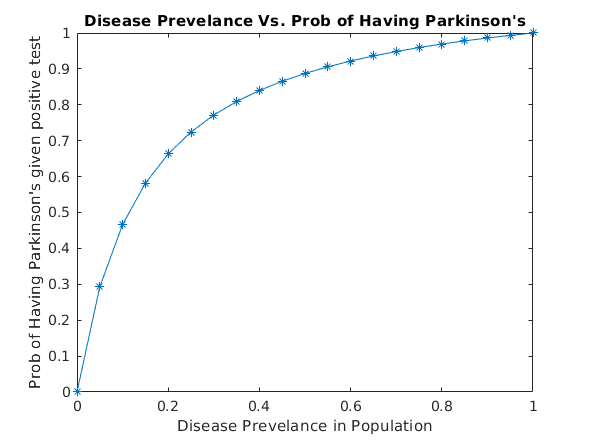

plot(range, probs_7, '*-')
title("Disease Prevelance Vs. Prob of Having Parkinson's");
xlabel('Disease Prevelance in Population'); %Label for x axis
ylabel("Prob of Having Parkinson's given positive test"); % Label for y axis

#### Exercise 8: At its current sensitivity and specificity, would you recommend that your screening test should be used for all people over 45 or only people who have displayed multiple symptoms of Parkinson’s? Why? What factors did you consider? (Your answer does not need to be limited to the values computed here.)

I would recommend that everyone over 45 get the screening test as the probability of them having Parkinson's given a positive test very low. 

## Applying Bayes Theorem to Speech Perception

This silly example of sensory perception is based on the first minute of this video from the show The Two Ronnies: [https://www.youtube.com/watch?v=0CmaLgxLDE0 (just the first minute).](https://www.youtube.com/watch?v=0CmaLgxLDE0.) Credit for the example belongs to Jim Stone's book *Bayes' Rule: A Tutorial Introduction to Bayesian Analysis. *While this example is an oversimplification, many researchers have proposed that the brain is essentially Bayesian.

The customer in a hardware store requests "fork handles", and the shopkeeper promptly provides him with "four candles". With their London accents, the terms "four candles" and "fork handles" are accoustically very similar. 

Let's assume that the brain holds a representation of the acousitc data for words and phrases. In the shopkeeper's experience (being a Londoner), when he imagines someone saying "fork handles", the probability of it sounding like what he just heard is 0.8, or P(acoustic data | "fork handles") = 0.8.  When he imagines someone saying "four candles", the probability of it sounding like what he just heard is 0.7.  In reality, these numbers might be challenging to actually determine, but let's assume that the brain holds this probabilistic representation. We see that the two values are similar and both reasonably large, since the acoustic data that the shopkeeper hears is consistent with both phrases. Note that these values are called likelihoods, and that the two values sum to more than 1, which is fine because they are unrelated pieces of information. These likelihoods tell us the the probabilities of the observed acoustic data given that each of the two possible phrases were spoken. However, that's not the question that the shopkeeper needs to answer to go fetch something from the shelf. The shopkeeper needs to answer: what is the probabiltiy that each of the two possible phrases were spoken given the acoustic data he heard? In conditional probabilities terms, we want to know P("fork handles" | acoustic data) and P("four candles" | acoustic data)... and in reality, the shopkeeper actually just needs to know which of these is greater (so he knows what to fetch). 

Now let's also suppose that the shopkeeper has some prior information about what people tend to ask for when they come into the shop. In the past, he's been asked for "four candles" a total of 90 times, and he's been asked for "fork handles" a total of 10 times. We'll also assume that the next customer who comes in will ask for one of those two things. 

We'll now use Bayes Theorem to explain the shopkeeper's interpretation of the acoustic data.

Often Bayes Theorem is framed in terms of hypotheses and data, so we'll switch the notation here to use D for data and Hx for some hypothesis x. Importantly, the data are always the same, but we might be evaluating more than one hypothesis.

$P\left(H_x \left|D\right.\right)=\frac{P\left(D\left|H_x \right.\right)\cdot P\left(H_x \right)}{P\left(D\right)}$ or $\textrm{posterior}=\frac{\textrm{likelihood}\cdot \textrm{prior}}{\textrm{marginal}\;\textrm{likelihood}}=\frac{\textrm{Bayes}\;\textrm{Numerator}}{\textrm{marginal}\;\textrm{likelihood}}$

In this example, we're evaluating two hypotheses, so things will be a little more complicated. We will make our lives easier by creating a blank table to help organize our information.

BayesTable = table('Size',[2 5],'VariableTypes',{'string','double','double','double','double'},'VariableNames',{'hypothesis','prior','likelihood','BayesNumerator','posterior'});
BayesTable.hypothesis = categorical({'FourCandles','ForkHandles'}')

BayesTable = 2×5 table
    hypothesis     prior    likelihood    BayesNumerator    posterior
    ___________    _____    __________    ______________    _________

    FourCandles      0          0               0               0    
    ForkHandles      0          0               0               0    


#### Exercise 9: Fill in the appropriate values below for the prior and the likelihood. 

These are currently set to zero as placeholders.

BayesTable.prior(BayesTable.hypothesis=='FourCandles') = .9; % Exercise: Fill in these values
BayesTable.prior(BayesTable.hypothesis=='ForkHandles') = .1; % Exercise: Fill in these values

BayesTable.likelihood(BayesTable.hypothesis=='FourCandles') = .7; % Exercise: Fill in these values
BayesTable.likelihood(BayesTable.hypothesis=='ForkHandles') = .8; % Exercise: Fill in these values

BayesTable.BayesNumerator = BayesTable.prior.* BayesTable.likelihood;
BayesTable.posterior = BayesTable.BayesNumerator ./ sum(BayesTable.BayesNumerator)

BayesTable = 2×5 table
    hypothesis     prior    likelihood    BayesNumerator    posterior
    ___________    _____    __________    ______________    _________

    FourCandles     0.9        0.7             0.63          0.88732 
    ForkHandles     0.1        0.8             0.08          0.11268 


#### Exercise 10: Explain the calculation of the denominator of the posterior invoking a previously mentioned law or rule.

Note: You should assume that "four candles" and "fork handles" are the only possible interpretations of the acoustic data (e.g., no one goes around exclaiming "for candles sake!"). 

The denominator is the marginal likelihood. This is the probability what was the thing said was actually said: like [P(data positive)]

#### Exercise 11: Given the calculations in the table, how does the shopkeeper interpret the acoustic data?

Interprets it as "four candles". posterior(four candles) = .8873 and posterior(fork handles) = .1127

#### Exercise 12: If it was the shopkeeper's first day on the job (so he has no information about what people tend to ask for in the store), what would the posterior probability be for "fork handles" given the acoustic data?

TODO: confused